Q1

x = [0.90  1.42  1.30  1.55  1.63 1.32  1.35  1.47  1.95  1.66 1.96  1.47  1.92  1.35  1.05 1.85  1.74  1.65  1.78  1.71 2.29  1.82  2.06  2.14  1.27]

x =                        0.9                      1.42                       1.3                      1.55                      1.63                      1.32                      1.35                      1.47                      1.95                      1.66                      1.96                      1.47                      1.92                      1.35                      1.05                      1.85                      1.74                      1.65                      1.78                      1.71                      2.29                      1.82                      2.06                      2.14                      1.27


mean(x)

ans =                     1.6244


median(x)

ans =                       1.65


mode(x)

ans =                       1.35


range(x)

ans =                       1.39


std(x)

ans =          0.339387683925036


var(x)

ans =                   0.115184


cof = (std(x)/mean(x))*100

cof =           20.8931103130409


Q2

x =[100 200 400 800 1000 1500 2000 5000 10000 20000 42195]

x =          100         200         400         800        1000        1500        2000        5000       10000       20000       42195


y_men = [9.58 19.19 43.18 100.90 131.96 206.00 284.79 757.40 1577.53 3386.00 7377.00]

y_men =                       9.58                     19.19                     43.18                     100.9                    131.96                       206                    284.79                     757.4                   1577.53                      3386                      7377


y_women = [10.49 21.34 47.60 113.28 148.98 230.07 325.35 851.15 1771.78 3926.60 8125.00]

y_women =                      10.49                     21.34                      47.6                    113.28                    148.98                    230.07                    325.35                    851.15                   1771.78                    3926.6                      8125


x_test = 21097.5

x_test =                    21097.5


x = log10(x)

x =                          2          2.30102999566398          2.60205999132796          2.90308998699194                         3          3.17609125905568          3.30102999566398          3.69897000433602                         4          4.30102999566398          4.62526099122088


y_men = log10(y_men)

y_men =          0.981365509078544          1.28307497473547          1.63528263799821          2.00389116623691          2.12044230687331          2.31386722036915           2.4545247355931          2.87932530078481           3.1979776270037          3.52968695377292          3.86787978345838


y_women = log10(y_women)

y_women =           1.02077548819356          1.32919441508845          1.67760695272049          2.05415324034569          2.17312796993821          2.36185999248929          2.51235081106987          2.93000610348259          3.24840979502416          3.59401666224808          3.90982336965091


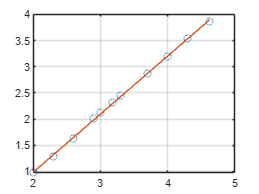

a =           1.10762326069588         -1.22780368700263


r2 =          0.999417135803562


[a,r2] = linregr(x,y_men)

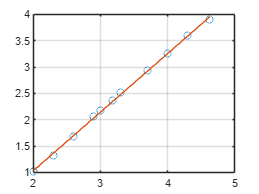

aw =           1.11148419697992         -1.19095224031498


rw2 =          0.999200911726766


[aw,rw2] = linregr(x,y_women)

alpha = 10 .^ a(2)

alpha =         0.0591829096677477


beta = a(1)

beta =           1.10762326069588


alphaw = 10 .^ aw(2)

alphaw =          0.064424010918049


betaw = aw(1)

betaw =           1.11148419697992


y_predic = alpha * (x_test.^beta)

y_predic =           3645.98727268712


y_predic = alphaw * (x_test.^betaw)

y_predic =           4124.41326847304


Q3

x = [ 0  2  4  6  9  11  12  15  17  19]

x =      0     2     4     6     9    11    12    15    17    19


y = [5  6  7  6  9  8    8    10  12  12]

y =      5     6     7     6     9     8     8    10    12    12


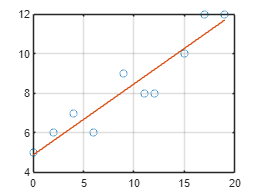

a =          0.359145527369826          4.88811748998665


r2 =          0.892884906307609


[a,r2] = linregr(x,y)

corre = sqrt(r2)

corre =          0.944925873445959


Sr = sum((y - a(2) - (a(1).*x)).^2)

Sr =           5.79492656875835


Sy_x = sqrt(Sr/(length(x)-2))

Sy_x =          0.851096834146852


Q4

x = [0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000]

x =                          0                       0.2                       0.4                       0.6                       0.8                         1                       1.2                       1.4                       1.6                       1.8                         2



y = [0.1409    0.1651    0.1506    0.2174    0.2374    0.2517    0.3091    0.3803    0.4700    0.5536    0.6137]

y =                     0.1409                    0.1651                    0.1506                    0.2174                    0.2374                    0.2517                    0.3091                    0.3803                      0.47                    0.5536                    0.6137



y = log(y)

y =           -1.9597048600775         -1.80120392805605         -1.89312796361634         -1.52601630429503         -1.43800879680657         -1.37951737684087         -1.17409042984407        -0.966794864047923        -0.755022584278033        -0.591312874678677        -0.488249069587086


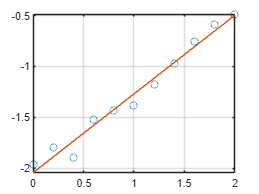

a =          0.772432752337875         -2.04270993889498


r2 =          0.975934092323986


[a,r2] = linregr(x,y)

alpha = exp(a(2))

alpha =          0.129676818036753


beta = a(1)

beta =          0.772432752337875


y_pre = alpha*exp(beta.*1.1)

y_pre =          0.303299682434234


Q5

x = [0.1   0.2   0.4   0.6   0.9   1.3   1.5   1.7   1.8]

x =                        0.1                       0.2                       0.4                       0.6                       0.9                       1.3                       1.5                       1.7                       1.8


y = [0.75 1.25 1.45 1.25 0.85 0.55 0.35 0.28 0.18]

y =                       0.75                      1.25                      1.45                      1.25                      0.85                      0.55                      0.35                      0.28                      0.18


Q8

x = [26.67    93.33    148.89     315.56]

x =                      26.67                     93.33                    148.89                    315.56


y = [1.35      0.085    0.012      0.00075]

y =                       1.35                     0.085                     0.012                   0.00075


x = log10(x)

x =           1.42602301568988          1.97002126582837          2.17286552991699          2.49908194738833


y = log10(y)

y =          0.130333768495006         -1.07058107428571         -1.92081875395238          -3.1249387366083


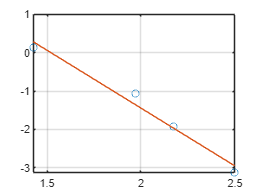

a =           -3.0133755348686          4.58147104630225


r2 =          0.975702914774901


[a,r2] = linregr(x,y)

alpha = 10 .^ a(2)

alpha =           38147.9360831019


beta = a(1)

beta =           -3.0133755348686


y_pre = alpha * (50.^beta)

y_pre =           0.28962523605278



x = [10 20 30 40 50 60 70 80]

x =     10    20    30    40    50    60    70    80



y = [25 70 380 550 610 1220 830 1450]

y =           25          70         380         550         610        1220         830        1450


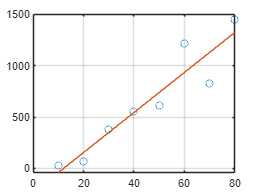

a =           19.4702380952381         -234.285714285714


r2 =          0.880485246781226


[a,r2] = linregr(x,y)

^HW9

Q1

x = [10 20 30 40 50 60 70 80]';
y = [25 70 380 550 610 1220 830 1450]';
Z = [x x.^2]

Z =           10         100
          20         400
          30         900
          40        1600
          50        2500
          60        3600
          70        4900
          80        6400


xtest = 45

xtest =     45


a = (Z'*Z) \ (Z'*y)

a =           7.77102446483184
           0.1190749235474


Sr = sum((y-Z*a).^2)

Sr =           230159.327217125


St = sum((y-mean(y)).^2)

St =                1808296.875


r2 = 1 - Sr/St

r2 =          0.872720386569752


syx = sqrt(Sr/length(x)-length(a))

syx =            169.61107246327


y_pre = ((a(1).*xtest) +(a(2).*xtest.^2))

y_pre =           590.822821100918


Q2

x = [0.5   1     2     3      4      5      6      7      9]';
y = [6      4.4  3.2  2.7   2      1.9    1.7   1.4   1.1]';
z = [exp(-1.5.*x) exp(-0.3.*x) exp(-0.05.*x)]

z =          0.472366552741015         0.860707976425058         0.975309912028333
          0.22313016014843         0.740818220681718         0.951229424500714
        0.0497870683678639         0.548811636094027          0.90483741803596
        0.0111089965382423         0.406569659740599         0.860707976425058
       0.00247875217666636         0.301194211912202         0.818730753077982
      0.000553084370147834          0.22313016014843         0.778800783071405
       0.00012340980408668         0.165298888221587         0.740818220681718
      2.75364493497472e-05         0.122456428252982         0.704688089718713
      1.37095908638408e-06        0.0672055127397498         0.637628151621773


xtest = 8

xtest =      8


a = (z'*z) \ (z'*y)

a =           4.13749657609789
          2.89588174529138
          1.53491994838069


Sr = sum((y-z*a).^2)

Sr =         0.0803481496914535


St = sum((y-mean(y)).^2)

St =           20.4088888888889


r2 = 1 - Sr/St

r2 =          0.996063080644474


syx = sqrt(Sr/length(x)-length(a))

syx =                           0 +      1.72947171928657i


A = a(1)

A =           4.13749657609789


B = a(2)

B =           2.89588174529138


C = a(3)

C =           1.53491994838069


y_pre = A.*exp(-1.5.*xtest)+ B.*exp(-0.3.*xtest)+ C.*exp(-0.05.*xtest)

y_pre =           1.29162149701814


Q3

x = [10 20 30 40 50 60 70 80]';
y = [25 70 380 550 610 1220 830 1450]';
Z = [ones(size(x)) x x.^2]

Z =            1          10         100
           1          20         400
           1          30         900
           1          40        1600
           1          50        2500
           1          60        3600
           1          70        4900
           1          80        6400


xtest = 45

xtest =     45


a = (Z'*Z) \ (Z'*y);
Sr = sum((y-Z*a).^2);
St = sum((y-mean(y)).^2);
r2 = 1 - Sr/St

r2 =          0.881771069281762


Q4

x1 = [0 1 1 2 2 3 3 4 4]'

x1 =      0
     1
     1
     2
     2
     3
     3
     4
     4



x2 = [0 1 2 1 2 1 2 1 2]'

x2 =      0
     1
     2
     1
     2
     1
     2
     1
     2



y = [15.1 17.9 12.7 25.6 20.5 35.1 29.7 45.4 40.2]'

y =                       15.1
                      17.9
                      12.7
                      25.6
                      20.5
                      35.1
                      29.7
                      45.4
                      40.2



z = [ones(size(x1)) x1 x2]

z =      1     0     0
     1     1     1
     1     1     2
     1     2     1
     1     2     2
     1     3     1
     1     3     2
     1     4     1
     1     4     2


xtest = 3

xtest =      3


a = (z'*z) \ (z'*y)

a =           14.4608695652174
          9.02521739130434
         -5.70434782608694


Sr = sum((y-z*a).^2);
St = sum((y-mean(y)).^2);
r2 = 1 - Sr/St

r2 =          0.995523346259294


syx = sqrt(Sr/(length(x1)-length(a)))

syx =           0.88878682988977


y_pre = a(1) + a(2).*xtest + a(3).*xtest

y_pre =           24.4234782608696


Q5

x1 = [5  10  15  20  25  30  35  40  45  50]

x1 =      5    10    15    20    25    30    35    40    45    50



y1 = [17  24  31  33  37  37  40  40  42  41]

y1 =     17    24    31    33    37    37    40    40    42    41


p = polyfit(x1,y1,1)

p =          0.494545454545454                      20.6


P = polyval(p,22)

P =                      31.48



x = log10(x1)

x =          0.698970004336019                         1          1.17609125905568          1.30102999566398          1.39794000867204          1.47712125471966          1.54406804435028          1.60205999132796          1.65321251377534          1.69897000433602


y = log10(y1)

y =           1.23044892137827          1.38021124171161          1.49136169383427          1.51851393987789          1.56820172406699          1.56820172406699          1.60205999132796          1.60205999132796           1.6232492903979          1.61278385671974


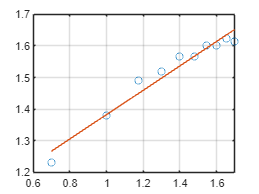

a =          0.385077205318534         0.997950299974558


r2 =          0.955262396619072


[a,r2] = linregr(x,y)

alpha = 10 .^ a(2)

alpha =           9.95291511128898


beta = a(1)

beta =          0.385077205318534


y_predic = alpha.* (22.^beta)

y_predic =           32.7255289035824



x = 1./x1

x =                        0.2                       0.1        0.0666666666666667                      0.05                      0.04        0.0333333333333333        0.0285714285714286                     0.025        0.0222222222222222                      0.02


y = 1./y1

y =         0.0588235294117647        0.0416666666666667         0.032258064516129        0.0303030303030303         0.027027027027027         0.027027027027027                     0.025                     0.025        0.0238095238095238         0.024390243902439


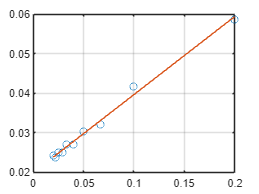

a =          0.197463573841957        0.0199632204843966


r2 =          0.993527170913219


[a,r2] = linregr(x,y)

alpha = 1./a(2)

alpha =           50.0921181921327


beta = alpha.*a(1)

beta =           9.89136867953224


ypre = alpha *(22./(beta+22))  

ypre =           34.5556382763276



p = polyfit(x1,y1,2)

p =         -0.016060606060606          1.37787878787878          11.7666666666667


polyval(p,22)

ans =           34.3066666666667


^HW10

Q1

x11 = [3  4  5]

x11 =      3     4     5


y11 = [0.9  0.941176  0.961538]

y11 =                        0.9                  0.941176                  0.961538


xtest = 0.93

xtest =                       0.93


true = sqrt( xtest ./ (1-xtest))

true =           3.64495737776374


Q2

f = @(x) x.^5 - 16.*x.^4 + 99.*x.^3 - 296.*x.^2 + 428.*x - 240

f = function_handle with value:
    @(x)x.^5-16.*x.^4+99.*x.^3-296.*x.^2+428.*x-240


xtest = 2.5

xtest =                        2.5


true = f(2.5)

true =                   -0.46875


x = [2 3]

x =      2     3


y = f(x)

y =      0     0


est = Lagrange(x,y,xtest)

est =      0


er = ((true - est) / true)*100

er =    100



x = [2 3 3.5]

x = 1×3
                         2                         3                       3.5


y = f(x)

y = 1×3
                         0                         0                   0.84375


est = Lagrange(x,y,xtest)

est =                   -0.28125


er = ((true - est) / true)*100

er =     40



x = [2 3 3.5 4]

x = 1×4
                         2                         3                       3.5                         4


y = f(x)

y = 1×4
                         0                         0                   0.84375                         0


est = Lagrange(x,y,xtest)

est =                   -0.84375


er = abs((true - est)/true)*100

er =     80


Q3

f = @(x) x.^5 - 16.*x.^4 + 99.*x.^3 - 296.*x.^2 + 428.*x - 240

f = function_handle with value:
    @(x)x.^5-16.*x.^4+99.*x.^3-296.*x.^2+428.*x-240


xtest = 2.5

xtest =                        2.5


true = f(2.5)

true =                   -0.46875


x = [2 3]

x = 1×2
     2     3


y = f(x)

y = 1×2
     0     0


est = Newtint(x,y,xtest)

est =      0


er = abs((true - est)/true)*100

er =    100


x = [2 3 3.5]

x = 1×3
                         2                         3                       3.5


y = f(x)

y = 1×3
                         0                         0                   0.84375


est = Newtint(x,y,xtest)

est =                   -0.28125


er = abs((true - est)/true)*100

er =     40


x = [2 3 3.5 4]

x = 1×4
                         2                         3                       3.5                         4


y = f(x)

y = 1×4
                         0                         0                   0.84375                         0


est = Newtint(x,y,xtest)

est =                   -0.84375


er = abs((true - est)/true)*100

er =     80


Q4

x = [2 3 4]

x = 1×3
     2     3     4


y = [0.5 0.33 0.25]

y = 1×3
                       0.5                      0.33                      0.25


p =polyfit(x,y,2)

p = 1×3
                     0.045                    -0.395                      1.11


Q5

f = @(x)5.*exp(0.25.*x)

f = function_handle with value:
    @(x)5.*exp(0.25.*x)


xtest = 12.5

xtest =                       12.5


true = f(xtest)

true =           113.799475467634


x = linspace(0,20,3)

x = 1×3
     0    10    20


y = f(x)

y = 1×3
                         5          60.9124698035174          742.065795512883


p = polyfit(x,y,2)

p = 1×3
          3.12620427952924         -25.6707958149406           4.9999999999997


est = polyval(p,xtest)

est =           172.584470989685


et = (abs(true - est) / true)*100

et =           51.6566489260938


%---------------
x = linspace(0,20,4)

x = 1×4
                         0          6.66666666666667          13.3333333333333                        20


y = f(x)

y = 1×4
                         5          26.4724502523501          140.158124472631          742.065795512883


p = polyfit(x,y,3)

p = 1×4
         0.222754934729273         -3.41769992494625          16.1053143828598          5.00000000000014


P = polyval(p,xtest)

P =           107.369048406008


et = (abs(true-P)/true)*100

et =           5.65066493953599


%---------------
x = linspace(0,20,5)

x = 1×5
     0     5    10    15    20


y = f(x)

y = 1×5
                         5          17.4517147873092          60.9124698035174          212.605410000314          742.065795512883


p = polyfit(x,y,4)

p = 1×5
        0.0128208076788996         -0.28166003709807          2.60144001724159         -5.07795716115677          4.99999999999982


P = polyval(p,xtest)

P =           110.891278195506


et = (abs(true - P) / true)*100

et =           2.55554541018473


HM11^

Q2    

x = [1.8 	   2 	     2.2 	2.4 	   2.6]

x = 1×5
                       1.8                         2                       2.2                       2.4                       2.6


y = [0.5815 	0.5767 	0.556 	0.5202 	0.4708]

y = 1×5
                    0.5815                    0.5767                     0.556                    0.5202                    0.4708


xtest = 2.1

xtest =                        2.1


int = interp1(x,y,xtest,"spline")

int =               0.5682984375


p =polyfit(x,y,4);
P =polyval(p,xtest)

P =              0.56830390625



cs = spline(x,y,xtest)

cs =               0.5682984375


Q3

x = [0 	100	200	400	600	800	1000]

x = 1×7
           0         100         200         400         600         800        1000


y = [0 	0.8244 	1.0000   0.7358	0.4060	0.1991	0.0916]

y = 1×7
                         0                    0.8244                         1                    0.7358                     0.406                    0.1991                    0.0916


nat = natspline(x,y,500)

nat =          0.560325706335617


notanot = spline(x,y,500)

notanot =          0.557567682926829


Q4

x = [0 	2 	4 	7 	10 	12]

x = 1×6
     0     2     4     7    10    12


y = [20 	20 	12 	7 	6 	6]

y = 1×6
    20    20    12     7     6     6


cs = spline(x,y,1.5)

cs =           21.3343531468531


Q5

x = [1 	2 	2.5 	3 	4 	5]

x = 1×6
                         1                         2                       2.5                         3                         4                         5


y = [1 	5 	7 	8 	2 	1]

y = 1×6
     1     5     7     8     2     1


nat = natspline(x,y,4.5)

nat =          0.718879668049793


cs = spline(x,y,4.5)

cs =         -0.525510204081633


Q6

x = [0 	8 	16 	24 	32 	40]

x = 1×6
     0     8    16    24    32    40


y = [14.621     11.843 	9.870 	8.418 	7.305 	6.413]

y = 1×6
                    14.621                    11.843                      9.87                     8.418                     7.305                     6.413


pi = interp1(x,y,27)

pi =                   8.000625


p = polyfit(x,y,5)

p = 1×6
     -9.66389973960624e-09      1.81070963541894e-06     -0.000163899739583411       0.00948567708333432        -0.413533333333336                    14.621


P = polyval(p,27)

P =           7.96823896026611


cs = spline(x,y,27)

cs =           7.96788802083333


Q7

x = [3 4.5 7 9]

x = 1×4
                         3                       4.5                         7                         9


y = [2.5 1 2.5 0.5]

y = 1×4
                       2.5                         1                       2.5                       0.5


nat = natspline(x,y,5)

nat =            1.1028897338403


HW12^^

Q1

f = @(x) (1-x-4.*x.^3 + 2.*x.^5)

f = function_handle with value:
    @(x)(1-x-4.*x.^3+2.*x.^5)


a = -2

a =     -2


b = 4

b =      4


p = [2 0 -4 0 -1 1]

p = 1×6
     2     0    -4     0    -1     1


q = polyint(p)

q = 1×7
         0.333333333333333                         0                        -1                         0                      -0.5                         1                         0


I_true = diff(polyval(q,[a,b]))

I_true =         1104


trap1 = abs(trap(f,a,b,1))

trap1 =         5280


et1 = (abs(I_true - trap1)/I_true)*100

et1 =           378.260869565217


trap2 =abs(trap(f,a,b,2))

trap2 =         2634


et2 = (abs(I_true - trap2)/ I_true)*100

et2 =           138.586956521739


trap4 = abs(trap(f,a,b,4))

trap4 =                   1516.875


et4 = (abs(I_true - trap4)/I_true)*100

et4 =            37.398097826087


ns = 1

ns =      1


%simpson
x = linspace(-2, 4, 2*ns+1);
total = 0

total =      0


for i = 1:ns
    il = 2*(i-1)+1;
    ir = 2*i+1;
    newx = x(il:ir);
    % newx(1) = x2
    % newx(2) = x1
    % newx(3) = x0
    h = (newx(1)-newx(3))./2
    I = h./3.*(f(newx(3)) + 4.*f(newx(2)) + f(newx(1)))
    total = total + I


end

h =     -3


I =        -1752


total =        -1752


abs(total)

ans =         1752


ns = 4

ns =      4


%simpson
x = linspace(-2, 4, 2*ns+1);
total = 0

total =      0


for i = 1:ns
    il = 2*(i-1)+1;
    ir = 2*i+1;
    newx = x(il:ir)
    % newx(1) = x2
    % newx(2) = x1
    % newx(3) = x0
    h = (newx(1)-newx(3))./2
    I = h./3.*(f(newx(3)) + 4.*f(newx(2)) + f(newx(1)))
    total = total + I


end

newx = 1×3
                        -2                     -1.25                      -0.5


h =                      -0.75


I =                2.806640625


total =                2.806640625


newx = 1×3
                      -0.5                      0.25                         1


h =                      -0.75


I =               -0.673828125


total =                  2.1328125


newx = 1×3
                         1                      1.75                       2.5


h =                      -0.75


I =              -42.966796875


total =              -40.833984375


newx = 1×3
                       2.5                      3.25                         4


h =                      -0.75


I =            -1065.697265625


total =                -1106.53125


abs(total)

ans =                 1106.53125


Q4

f =@(x) 5+0.25.*x.^2;
a = 0;
b = 11;
p = [0.25 0 5]

p = 1×3
                      0.25                         0                         5


q = polyint(p)

q = 1×4
        0.0833333333333333                         0                         5                         0


I_true = diff(polyval(q,[a,b]))

I_true =           165.916666666667



trap1 = trap(f,a,b,11)

trap1 =                    166.375


14

x = [0 	0.05    0.1    0.15    0.2    0.25 	  0.3     0.35]

x = 1×8
                         0                      0.05                       0.1                      0.15                       0.2                      0.25                       0.3                      0.35


y = [0 	10 	   28      46      63 	82 	  110    130]

y = 1×8
     0    10    28    46    63    82   110   130


p = polyfit(x,y,6)

p = 1×7
1.0e+00 *

         -1111111.11111095          944102.564102381         -264700.854700774          23682.4009323842          1059.95532245698          116.775641025581      -0.00903263403260785


f = @(x) polyval(p,x)

f = function_handle with value:
    @(x)polyval(p,x)


I = integral(f,0,0.35)

I =           20.2181915509259


P = polyint(p)

P = 1×8
1.0e+00 *

         -158730.158730136          157350.427350397         -52940.1709401549          5920.60023309604          353.318440818992          58.3878205127906      -0.00903263403260785                         0


I = diff(polyval(P,[0,0.35]))

I =           20.2181915509259
